# **Example: Generic Deep Autoencoder for Time-Series**

**Author:** Anika Terbuch

**History:** \change{1.0}{28-Apr-2022}{Original}

\change{2.0}{10-Jan-2023}

**Source:** Chair of Automation, University of Leoben, Austria

*email:* [automation@unileoben.ac.at](mailto:automation@unileoben.ac.at) *url:* automation.unileoben.ac.at

(c) 2023, Anika Terbuch

This script shows the use of the framework "AutoencoderDeep".

## Workspace

Clear the workspace.

clear all
close

### Path settings

Set the current directory to the path of this file.

filePath = matlab.desktop.editor.getActiveFilename;
[pathstr,name,ext]  = fileparts(filePath);
parentDir=fileparts(pathstr);

set the current directory in matlab to the root folder of this toolbox

cd(parentDir);

add all folders of the toolbox to the matlab path

addpath(genpath(parentDir));

## Data ingestion

Comment: this data set is available from Matlab 2022a on.

This implementation was created using Matlab 2022b.

The data set consits of multi-variate time series (3 channels) with varying number of time-steps per sample (varying time-series length).

load WaveformData

### Devide the data into sets for training and validation

Get the number of samples included in the data set `WaveformData.`

numObservations = numel(data);

Define the percentage of data that should be used for training. 

splitTrain=0.1;

Assign the data samples based on the `splitTrain` to the training and validation set.

XTrain = data(1:floor(splitTrain*numObservations));
XValidation = data(floor(splitTrain*numObservations)+1:end);


clear the variable data after it was splitted into sub-sets and is not used anymore

clear data

## Create first autoencoder

The first step is to crate a simple autoencoder and train it on the data prepared above.

The first example showing the use of the toolbox consists of training an autoencoder deep on the training-data `XTrain` and then reconstructing the validation-set `XValidation.`

### `Train the first AutoencoderDeep`

Training an autoencoder: Call the function `trainAutoenocoderDeep` and pass the training data `XTrain` as input parameter to the function.

ae=trainAutoencoderDeep(XTrain);

ans = struct with fields:
           AutoencoderType: 'VAE'
             LayersEncoder: {'FC'  'LSTM'}
             LayersDecoder: {'LSTM'}
            NeuronsEncoder: [50 20]
            NeuronsDecoder: 30
                 LatentDim: 2
               NumberEpoch: 10
             NumberFeature: 1
              LearningRate: 0.0500
             MiniBatchSize: 15
      ExecutionEnvironment: 'auto'
               WeightingKL: 1
    OutputTransferFunction: 'none'


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).


### Reconstruct / predict the data of the validation-set

Use the just trained Autoencoder to make a prediction / produce a reconstruction of the data.

Reconstruct the first ten samples of the validation-set

XValidation10=XValidation(1:10);
YValidation=predictAutoencoderDeep(XValidation10,ae)

YValidation = 10×1 cell array
    {3×200 single}
    {3×144 single}
    {3×170 single}
    {3×188 single}
    {3×147 single}
    {3×130 single}
    {3×146 single}
    {3×105 single}
    {3×159 single}
    {3×153 single}


### Result visualization

Visualize the first reconstructed time-series sample and the original data of the first sample passed to the autoencoder.

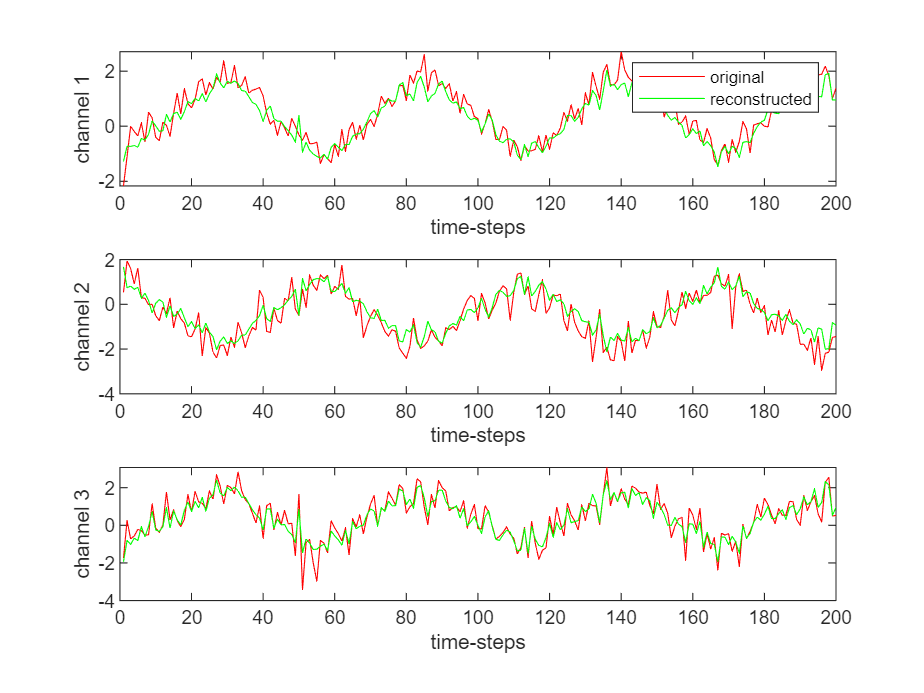

firstReconstructed=YValidation{1};
firstOriginal=XValidation{1};
figure()
%plot the reconstruction of the first channel
subplot(3,1,1)
plot(firstOriginal(1,:),'r')
hold on;
plot(firstReconstructed(1,:),'g')
legend('original','reconstructed')
xlabel('time-steps')
ylabel('channel 1')
% plot the reconstruction of the second channel
subplot(3,1,2)
plot(firstOriginal(2,:),'r')
hold on;
plot(firstReconstructed(2,:),'g')
xlabel('time-steps')
ylabel('channel 2')
% plot the reconstruction of the third channel
subplot(3,1,3)
plot(firstOriginal(3,:),'r')
hold on;
plot(firstReconstructed(3,:),'g')
xlabel('time-steps')
ylabel('channel 3')